# Problema 2 - Tp7

## Consigna

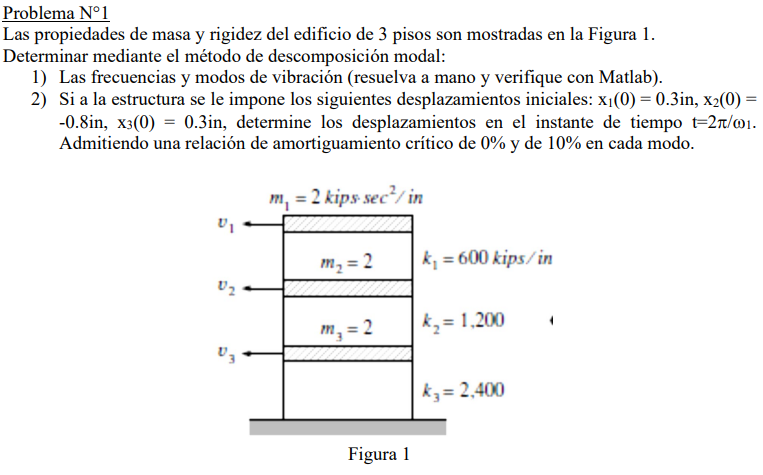

## Respuesta para comparar resultados

## Matrices M y K

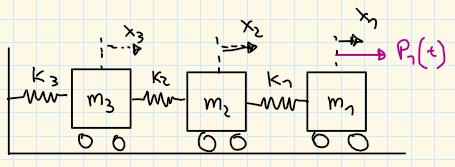

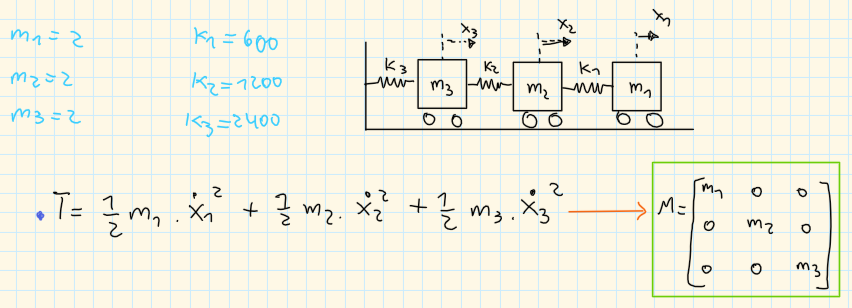

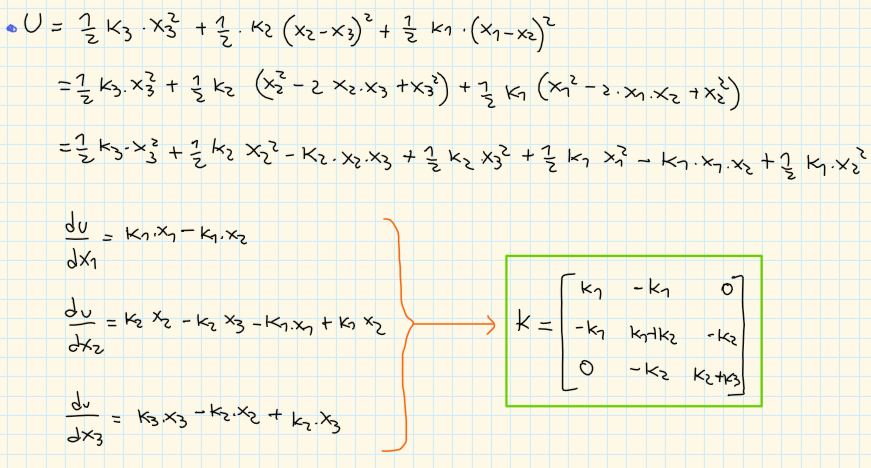

## Solución

clc; clear;

%% ---------------- DATOS DEL SISTEMA (EJ1) -----------------------

%Masas
m1=2;
m2=2;
m3=2;
M = diag([m1,m2,m3]);

%Rigidez
k1=600;
k2=1200;
k3=2400;
K = [k1 -k1    0;
    -k1 k1+k2  -k2;
    0   -k2    k2+k3];

%Condiciones iniciales
x0 = [0; 0; 0]; %Desplazamientos iniciales
dx0 = [0; 0; 0] ; %Velocidades iniciales

%Tiempo para graficar
tf=2;
dt=0.01;
t=0:dt:tf;

%Relacion de amortiguamiento crítico
zitta = [0.1; 0.1; 0.1];

%% ------------------ AUTOVECTORES Y AUTOVALORES ------------------

[V,lambda] = eig(K,M);
w = diag(sqrt(lambda))

w =    11.6511
   27.4598
   45.9370


V_norm = V ./ V(1,:)

V_norm =     1.0000    1.0000    1.0000
    0.5475   -1.5135   -6.0340
    0.1974   -0.8682   11.6708



%% ----------------- FUERZA ---------------------------------------
PoN = 5000; %[N]
Po = 1.124;
wp = 1.1*w(1);

%Vector fuerza
P = zeros(length(M),length(t));
P(1,:) = Po.*sin(wp*t);

%% ----------------- MATRICES MODALES -----------------------------

Mmodal = round(V' * M * V);
Kmodal = round(V' * K * V);
Cmodal = 2*zitta.*w.*eye(size(M));
Y0 = V' * M * x0;                   %desplazamiento inicial en coordenadas modales
dY0 = V' * M * dx0;                 %velocidad inicial en coordenadas modales
Pmodal = V' * P;                    %Paso fuerza a coordenadas modales
PoModal = V' * [Po; 0; 0];          %Paso las amplitudes de las fuerzas a coordenadas modales

%% ----------------- SOLUCION A LA EDO ----------------------------

%Tenemos un sistema de tipo Mmodal*y''+Cmodal*y'+Kmodal=Pmodal
%Cuya solución es y(t) = ytransitoria + ypermanente
%PERO EL EJERCICIO PIDE SOLO EVALUAR LA RESPUESTA PERMANENTE

%la respuesta permanente es
%ypermanente = ro * cos(wp*t-phi) donde rho es la amplitud y phi es el
%angulo de atraso
%rho(j)=Fo(j)/(k(j)*sqrt( (1-beta^2)^2 + (2*zitta*beta)^2 ))
%phi(j)=atan(2*zitta*beta/(1-beta^2));

%Cosas que necesito para calcular la solucion
e=exp(1);
wd = w.*sqrt(1-zitta.^2); %frecuencia natural del sistema amortiguado
beta = zeros(length(w),1);
phi = zeros(length(w),1);
rho = zeros(length(w),1);
D = zeros(length(w),1);


for i=1:length(w)
    beta(i)=wp/w(i);
    D(i) = 1/sqrt( (1-beta(i)^2)^2 + (2*zitta(i)*beta(i))^2 );
    phi(i)=atan(2*zitta(i)*beta(i)/(1-beta(i)^2));
    PoModal(i)=max(abs(Pmodal(i,:)));
    rho(i)=(PoModal(i)/Kmodal(i,i))*D(i);
end



PoModal

PoModal =     0.6868
    0.3951
    0.0603


D

D =     3.2880
    1.2695
    1.0824




Y = zeros(length(w), length(t));

for i = 1:length(w)    
    Y(i,:) = rho(i,:).*sin(wp*t-phi(i));
end


%Ahora paso de coordenadas modales a geométricas
X = V * Y;

%Muestro para los valores de rho y phi para comparar con la respuesta
phi

phi =    -0.8086
    0.1188
    0.0604


rho

rho =     0.0166
    0.0007
    0.0000


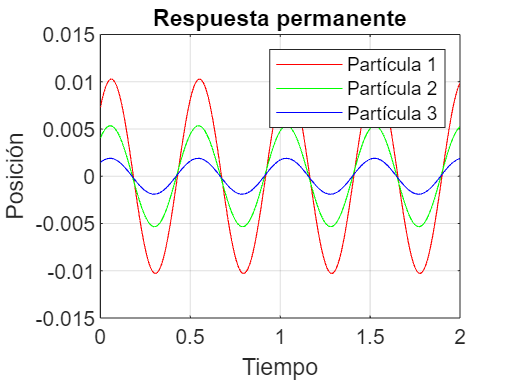


% Graficar las posiciones de las partículas
figure
plot(t, X(1,:), 'r', t, X(2,:), 'g', t, X(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2', 'Partícula 3');
title('Respuesta permanente');
grid on

## Solución teórica para comparar


rho_sol = [4.1266; 2.6266; 1.1552];
phi_sol = [-0.8086; 0.1188; 0.0604];

Y_sol=rho_sol.*sin(wp*t-phi_sol)

Y_sol =     2.9849    3.3246    3.6098    3.8357    3.9988    4.0962    4.1265    4.0891    3.9846    3.8147    3.5823    3.2911    2.9460    2.5525    2.1171    1.6470    1.1499    0.6340    0.1076   -0.4205   -0.9418   -1.4476   -1.9296   -2.3800   -2.7913   -3.1569   -3.4707   -3.7275   -3.9232   -4.0546   -4.1194   -4.1167   -4.0465   -3.9098   -3.7091   -3.4475   -3.1293   -2.7599   -2.3451   -1.8919   -1.4076   -0.9003   -0.3782    0.1501    0.6760    1.1907    1.6859    2.1535    2.5858    2.9756
   -0.3113    0.0246    0.3601    0.6897    1.0079    1.3097    1.5899    1.8441    2.0680    2.2581    2.4110    2.5244    2.5965    2.6259    2.6122    2.5557    2.4573    2.3186    2.1418    1.9299    1.6864    1.4152    1.1207    0.8079    0.4819    0.1479   -0.1885   -0.5218   -0.8465   -1.1574   -1.4492   -1.7173   -1.9573   -2.1651   -2.3374   -2.4714   -2.5648   -2.6162   -2.6246   -2.5900   -2.5129   -2.3946   -2.2370   -2.0427   -1.8149   -1.5574   -1.2743   -0.9703   -0.6504 

X_sol=V*Y_sol

X_sol =     1.7110    2.0446    2.3447    2.6064    2.8253    2.9979    3.1212    3.1934    3.2132    3.1803    3.0953    2.9594    2.7751    2.5452    2.2735    1.9646    1.6234    1.2556    0.8672    0.4646    0.0544   -0.3568   -0.7620   -1.1548   -1.5287   -1.8774   -2.1954   -2.4773   -2.7187   -2.9154   -3.0643   -3.1629   -3.2097   -3.2038   -3.1453   -3.0353   -2.8755   -2.6685   -2.4177   -2.1273   -1.8020   -1.4471   -1.0685   -0.6724   -0.2652    0.1463    0.5554    0.9554    1.3398    1.7021
    1.1870    1.0740    0.9434    0.7973    0.6382    0.4685    0.2912    0.1091   -0.0747   -0.2574   -0.4358   -0.6071   -0.7684   -0.9171   -1.0508   -1.1673   -1.2645   -1.3411   -1.3956   -1.4273   -1.4355   -1.4202   -1.3816   -1.3204   -1.2375   -1.1342   -1.0124   -0.8740   -0.7212   -0.5566   -0.3829   -0.2029   -0.0196    0.1641    0.3451    0.5204    0.6871    0.8426    0.9843    1.1098    1.2172    1.3045    1.3705    1.4140    1.4343    1.4310    1.4043    1.3546    1.2826 

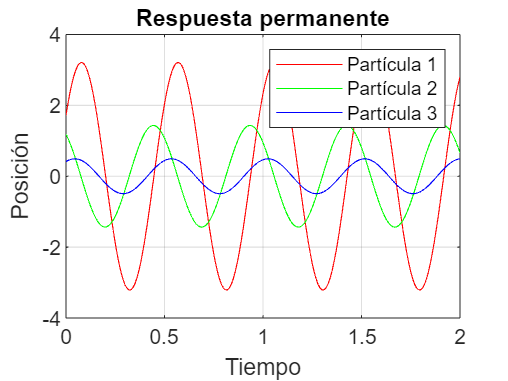

figure
plot(t, X_sol(1,:), 'r', t, X_sol(2,:), 'g', t, X_sol(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2', 'Partícula 3');
title('Respuesta permanente');
grid on